Scratch Pad for testing of features.

Read in audio files

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR10FFTdf25";

% Find data examples directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

Wavelet transform to Scaleograms

% Read in first audio file
% Steller Jay
[x,fs] = audioread(fullfile(datadir,contaminationFiles(12)));
[n,fn] = audioread(fullfile(datadir,signalFiles(12)));

n_scaled = (n-min(n))*(max(x)-min(x))/(max(n)-min(n)) + min(x);
z = (x(1:(fs*2)) + n_scaled(1:(fs*2)))/2;

audiowrite(fullfile(datadir,"test.wav"),z,fs);

% record or block duration (s)
tblock = 1;

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.25;

% frequency limits for octave 
freqlim = [30 20000];

nblock = tblock*fs;
noverlap = round(foverlap*nblock);

xblock = spectralReshape(z,noverlap,nblock);
firstBlock = xblock(:, 1);
planeblock = spectralReshape(n,noverlap,nblock);
firstNBlock = planeblock(:, 1);

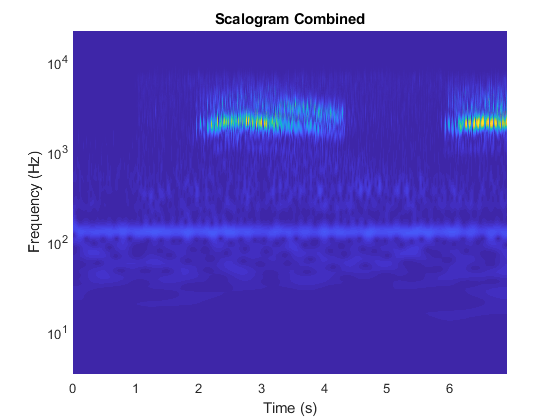

signalLength = tblock * fs;
% Write out plot of scaleogram
fb = cwtfilterbank('SignalLength',signalLength,...
    'SamplingFrequency',fs,...
    'VoicesPerOctave',12);
[cfs,frq] = wt(fb,firstBlock);
t = (0:signalLength-1)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram Combined');xlabel('Time (s)');ylabel('Frequency (Hz)')

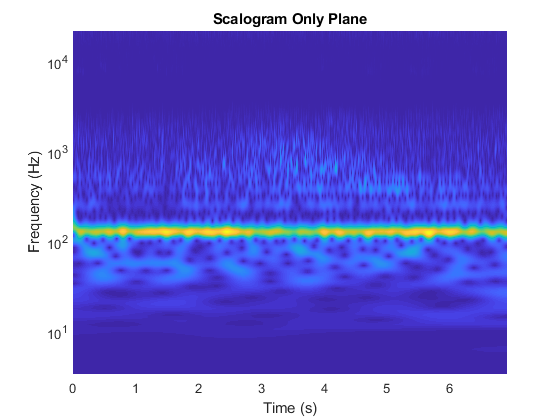


signalLength = tblock * fs;
% Write out plot of scaleogram
fb = cwtfilterbank('SignalLength',signalLength,...
    'SamplingFrequency',fs,...
    'VoicesPerOctave',12);
[cfs,frq] = wt(fb,firstNBlock);
t = (0:signalLength-1)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram Only Plane');xlabel('Time (s)');ylabel('Frequency (Hz)')